# sensitivity_with_year

% clear;
close all
addpath('E:\Dong\SPH Dropbox\Wang Dong\Shared Flu Forecast\Programme\mechanistic\mcmcstat-master');
Model_scripts = {'_5Base+AH+T+O+H'};
address = Model_scripts;
% cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
     cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal_retro\_5Base+AH+T+O+H")
% cd ("_5Base+AH+T+O+H_NPI_6")
Years_CF = [2013,2015,2016,2017,2018,2019];
lims = [0.025,0.5,0.975];
N=1000;
load('ili_proxy_2010_2020.mat')
npistart=525;
Rshort_day = npistart:npistart+7; Rshort_day1 = 518:npistart; Rshort_day2 = npistart:533; %
Pshort_day1 = 708+15:715+15; Pshort_day2=687:708+14;Rshort_day3=526:532;
Rlong_day1 = 517:577;Rlong_day2 = 525:577;Rlong_day3 = 526:577;
PLong_day1 = 685:708+14;PLong_day2 = 708+14:759+14;

npistart=525;
Rshort_day = 466:npistart+7; Rshort_day1 = 466:npistart+7; Rshort_day2 = npistart:533; %
Pshort_day1 = 722-52:729; Pshort_day2=671:722;Rshort_day3=526:532;
Rlong_day1 = 466:577;Rlong_day2 = 466:577;Rlong_day3 = 526:577;
PLong_day1 = 671:722;PLong_day2 = 722-52:773;

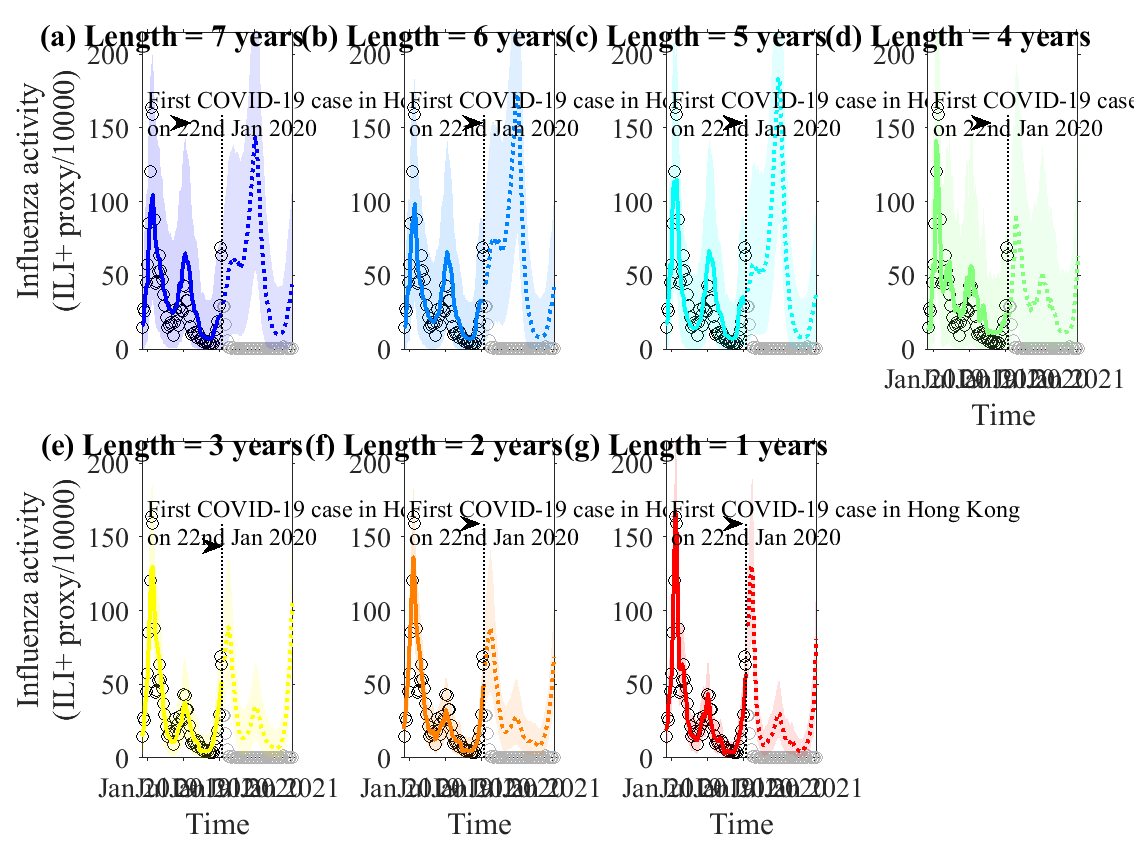

close all
Name = {'(a) Length = 7 years','(b) Length = 6 years','(c) Length = 5 years','(d) Length = 4 years','(e) Length = 3 years','(f) Length = 2 years','(g) Length = 1 years'};
figure("Name","Forecasting");ha = tiledlayout(2,4,'TileSpacing','Compact','Padding','compact');
yearshort_CF       =[2013,2014,2015,2016,2017,2018,2019];
Model_scripts{16}= '_5Base+AH+T+O+H';
for col = 1:7
    load(sprintf('ABase_%d.mat',yearshort_CF(col)),'PIdata');
    nexttile
    plot_forecasting(PIdata(:,end-111:end),A,525,52,getColor(col,1,8));
    set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',14);
set(get(gca,'YLabel'),'FontSize',14);
set(get(gca,'XLabel'),'FontSize',14);
    set(gca,'xtick',[470.25:4.4*6:577]);xlim([466,525+52]);
    set(gca, 'TickDir', 'out');
    plot([525.4 525.4],[0 160],':','color',[0 0 0],'LineWidth',1)
text(470,160,sprintf('First COVID-19 case in Hong Kong\non 22nd Jan 2020'),'FontSize',12,'FontName','Times New Roman')
plotarrow(518,525.4, 160,160)
title(Name(col), 'FontSize', 10, 'FontName', 'Times New Roman', 'Units', 'normalized', 'Position', [0.2, 0.935, 0]);
if col>3
    set(gca,'xticklabel',{'Jan 2019','Jul 2019','Jan 2020','Jul 2020','Jan 2021'},'XTickLabelRotation',0);
    xlabel('Time');
else
    set(gca,'xticklabel',{''},'XTickLabelRotation',0);
end

if col==1 ||col==5
ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
end
end

%exportgraphics(gcf,sprintf('Figure S4 sensitivity 2020_21.pdf',1),'ContentType','vector')
%

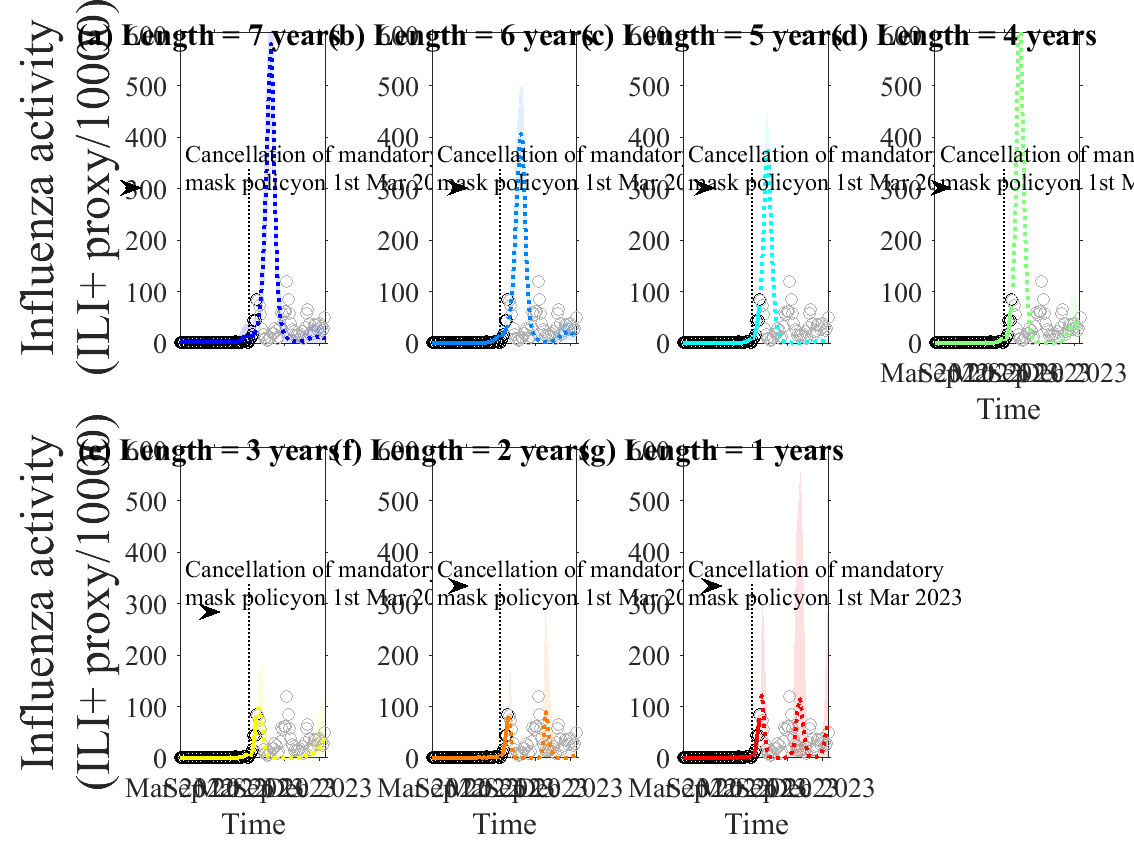

close all
Name = {'(a) Length = 7 years','(b) Length = 6 years','(c) Length = 5 years','(d) Length = 4 years','(e) Length = 3 years','(f) Length = 2 years','(g) Length = 1 years'};
figure("Name","Forecasting");ha = tiledlayout(2,4,'TileSpacing','Compact','Padding','compact');
cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal\_5Base+AH+T+O+H_NPI_6")
yearshort_CF       =[2016,2017,2018,2019,2020,2021,2022];
Model_scripts{16}= '_5Base+AH+T+O+H_NPI_6';
load('ABase_2019.mat', 'A')
for col = 1:7
    load(sprintf('ABase_%d.mat',yearshort_CF(col)),'PIdata');
    nexttile
    plot_forecasting_p(PIdata(:,end-111:end),A,688,52,getColor(col,1,8),6);
%     plot_forecasting(PIdata(:,end-111:end),A,525,52,getColor(col,1,8));
    set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',14);
set(get(gca,'YLabel'),'FontSize',14);
set(get(gca,'XLabel'),'FontSize',14);
    title(Name(col), 'FontSize', 10, 'FontName', 'Times New Roman', 'Units', 'normalized', 'Position', [0.2, 0.935, 0]);
    set(gca,'xtick',[636:4.4*6:759]);
ylim([0,605]);
    xlim([636,694+52]);
    set(gca, 'TickDir', 'out');
    plotarrow(660.5,668.0,340,340)
    plot([688.1 688.1],[0 340],':','color',[0 0 0],'LineWidth',1)
    text(640,342,sprintf('Cancellation of mandatory\nmask policyon 1st Mar 2023'),'FontSize',12,'FontName','Times New Roman')
    
if col>3
    set(gca,'xticklabel',{'Mar 2022','Sep 2022','Mar 2023','Sep 2023','Dec 2023'},'XTickLabelRotation',0);
     xlabel('Time');
else
    set(gca,'xticklabel',{''},'XTickLabelRotation',0);
end
if col==1 ||col==5
ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'),'FontSize',24);
end
end

 % exportgraphics(gcf,sprintf('Figure S11 sensitivity 2023_24.pdf',1),'ContentType','vector')

 


times=1;
 for x=1:1:60
    y(times)=sigmoid(0.09845,x);
    if times>=2
        ratio(times-1) = (y(times)-y(times-1))/1;
    end 
    times = times + 1;
 end
 x=1:59

times=1;
 for x=-10:1:40
    y(times)=exp(-0.0023*x);
   
    if times>=2
        ratio(times-1) = (y(times)-y(times-1))/y(times-1);
    end 
    times = times + 1;
 end